# Perlin Noise

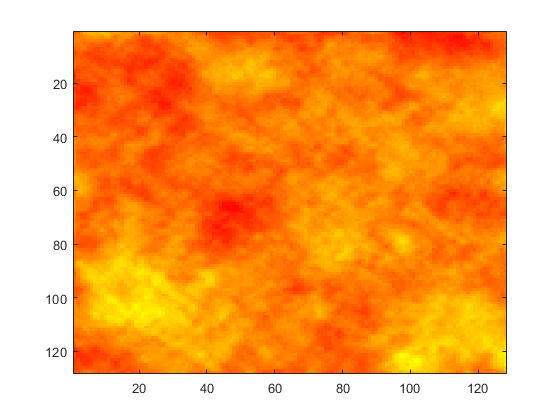

n = 128;
m = 128;
im = zeros(n, m);
im = perlin_noise(im);
figure; imagesc(im); colormap autumn;

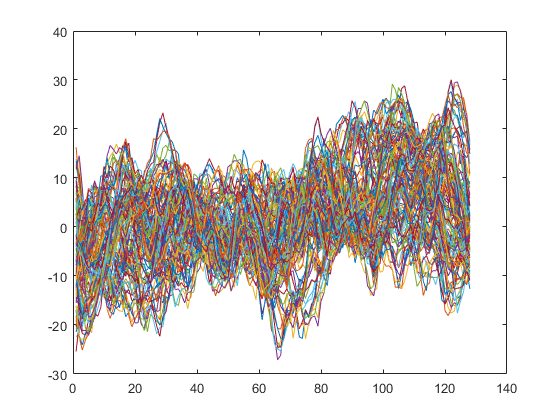

plot(im)

function im = perlin_noise(im)

    [n, m] = size(im);
    i = 0;
    w = sqrt(n*m);

    while w > 3
        i = i + 1;
        d = interp2(randn(ceil((n-1)/(2^(i-1))+1),ceil((m-1)/(2^(i-1))+1)), i-1, 'spline');
%         index_sub=d<0;
%         index_sup=d>0;
%         d(index_sub)=-20;
%         d(index_sup)=20;
        im = im + i * d(1:n, 1:m);
        w = w - ceil(w/2 - 1);
    end
%     index_sub=im<0;
%     index_sup=im>=0;
%     im(index_sup)=100;
%     im(index_sub)=-100;
end